# Snake-robot simulation & visualisation

#### ***Original Authors: Anna Sibilska-Mroziewicz, Jakub Możaryn,***

#### Ayesha ***)***Hameed, Maria Molina Fernandez, Andrzej Ordys

***Modified by: Pulkit Paliwal and Hemanta Hazarika***

## Initial parameters

clc;
clear;

Number of robot segments:

param.N  = 10;

Snake parameters (mass: m; length: 2l):

param.m  = 1;
param.l  = 0.07;

Friction coefficients:

param.ct = 1;
param.cn = 10;

Controler parameters:

param.Kp  = 1; %%%***
param.Kd  = 2; %%%***
param.st1 = 1; % path following parameter - for 0 - without following
param.st2 = 2; % path following parameter - can't be equal to zero (division)
param.st3 = 0.5; %%%***

Simulation time:

t = 0:0.01:300;

Reference trajectory parameters:

param.delta_u = deg2rad(3);
param.ampli_u = deg2rad(20);
param.omega_u = deg2rad(50);

Position of the point we want to follow:

%start with x=0; y=2
Px=[15];
Py=[0];
param.Px=Px;
param.Py=Py;
global flag;
flag=zeros(1,size(param.Px,1));

## Reference signal

fi_r=zeros(1,param.N-1);
 
for i = 1:param.N-1
%      fi_z = param.ampli_u*sin(param.omega_u*t+(i-1)*param.delta_u);
     fi_z = novel_wave(t, param.ampli_u, param.omega_u, i, param.delta_u);
     fi_zad{i}=fi_z;
     fi_r(i)=fi_z(1);
end

## Boundary conditions

Initial link  and joint angles and velocities:

theta    = zeros(param.N,1);
thetaDot = zeros(param.N,1);
fi       = fi_r;
fiDot    = zeros(param.N-1,1);

Mass centers position:

xCm     = 0;
yCm     = 0;
p       = [xCm; yCm];
xCmDot  = 0;
yCmDot  = 0;
pDot    = [xCmDot; yCmDot];

Rearangement of boundary conditions (A - actuated, U - unactuated):

qA0    = fi';
qU0    = [theta(param.N); p];
qADot0 = fiDot;
qUDot0 = [thetaDot(param.N); pDot];
x0     = [qA0; qU0; qADot0; qUDot0];

## Model Changes

Geometric constrains

$\begin{array}{l}
x_{i+1}-x_{i}=l \cos \theta_{i}+l \cos \theta_{i+1} \\
y_{i+1}-y_{i}=l \sin \theta_{i}+l \sin \theta_{i+1}
\end{array}$,

Using the notation from Sect. 2.3, D and A  we can write the joint constraints for all the links of the robot in matrix form as 

$\begin{array}{l}
\mathbf{D X}+l \mathbf{A} \cos \theta=\mathbf{0} \\
\mathbf{D Y}+l \mathbf{A} \sin \theta=\mathbf{0}
\end{array}$.

We can now express the position of the individual links as a function of the CM position and the link angles of the robot by combining (2.4) and (2.7a)–(2.7b) into 

$\begin{array}{l}
\mathbf{T X}=\left[\begin{array}{c}
-l \mathbf{A} \cos \theta \\
p_{0,x}
\end{array}\right] \\
\mathbf{T Y}=\left[\begin{array}{c}
-l \mathbf{A} \sin \theta \\
p_{0,y}
\end{array}\right]
\end{array}$,

where:

$\mathbf{T}=\left[\begin{array}{c}
\mathbf{D} \\
\mathbf{a}^{T}
\end{array}\right] \in \mathbb{R}^{N \times N}$ and $a^T =\left\lbrack \begin{array}{cccc}
0 & \ldotp \ldotp \ldotp  & 0 & 1
\end{array}\right\rbrack$.

It can be shown that:

$\mathbf{T}^{-1}=\left[\begin{array}{c}
\mathbf{C} ,\ 
\mathbf{e}
\end{array}\right] \in \mathbb{R}^{N \times N}$ and $\mathit{\mathbf{C}}=\left\lbrack \begin{array}{cccc}
0 & 0 & \ldotp \ldotp \ldotp  & 0\\
-1 & 0 & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp \\
-1 & -1 & \ldotp \ldotp \ldotp  & 0\\
-1 & -1 & \ldotp \ldotp \ldotp  & -1
\end{array}\right\rbrack$$ \in \mathbb{R}^{N \times N-1}$:

Solving for X and Y:


$$\mathbf{X}=\mathbf{T}^{-1}\left[\begin{array}{c}
-l \mathbf{A} \cos \theta \\
p_{0,x}
\end{array}\right]=-l  \mathbf{C}  \mathbf{A} \cos \theta+\mathbf{e} p_{0,x}, \\
$$



$$\mathbf{Y}=\mathbf{T}^{-1}\left[\begin{array}{c}
-l \mathbf{A} \sin \theta \\
p_{0,y}
\end{array}\right]=-l \mathbf{C} \mathbf{A}\sin \theta+\mathbf{e} p_{0,y},$$



$$\mathbf{\dot{X}}=l  \mathbf{C}  \mathbf{A} \mathbf{S}_{\theta} \dot{\theta}+\mathbf{e} \dot{p}_{0,x}, \\
$$



$$\dot{\mathbf{Y}}=-l  \mathbf{C}  \mathbf{A} \mathbf{C}_{\theta} \dot{\theta}+\mathbf{e} \dot{p}_{0,y}\\$$


Dynamical equations of motion. 

By substitution of 2.27a & 2.27b into 2.29.


$$a^{T}=\left[ 1, 0, 0 ... 0\right] \in \mathbb{R}^{N }$$


$p_{0,x}=a^{T}X$, 


$$p_{0,y}=a^{T}Y$$



$$m \ddot{\mathbf{p}}_0=m\left[\begin{array}{l}
\ddot{p}_{0,x} \\
\ddot{p}_{0,y}
\end{array}\right]=
\left[\begin{array}{l}
\mathbf{a}^{T} \ddot{\mathbf{X}} \\
\mathbf{a}^{T} \ddot{\mathbf{Y}}
\end{array}\right]
=
\left[\begin{array}{l}
\mathbf{a}^{T}( \mathbf{f}_{R, x}+\mathbf{D}^{T}\mathbf{h}_x) \\
\mathbf{a}^{T} (\mathbf{f}_{R, y}+\mathbf{D}^{T}\mathbf{h}_y))
\end{array}\right]$$



$$m \ddot{\mathbf{p}}_0 - m l
\left[\begin{array}{l}
\mathbf{a}^{T}\mathbf{D}^{T}\left(\mathbf{D D}^{T}\right)^{-1}\mathbf{A}\mathbf{S}_{\theta} \ddot{{\theta}}\\
-\mathbf{a}^{T}\mathbf{D}^{T}\left(\mathbf{D D}^{T}\right)^{-1}\mathbf{A}\mathbf{C}_{\theta} \ddot{{\theta}}
\end{array}\right]-
m l 
\left[\begin{array}{l}
\mathbf{a}^{T}\mathbf{D}^{T}\left(\mathbf{D D}^{T}\right)^{-1}\mathbf{A}\mathbf{C}_{\theta} \dot{{\theta}}^{2}\\
\mathbf{a}^{T}\mathbf{D}^{T}\left(\mathbf{D D}^{T}\right)^{-1}\mathbf{A}\mathbf{S}_{\theta} \dot{{\theta}}^{2}
\end{array}\right] 
-
\left[\begin{array}{l}
\left(\mathbf{a}^{T}-\mathbf{a}^{T}\mathbf{D}^{T}\left(\mathbf{D D}^{T}\right)^{-1}\mathbf{D}\right) \mathbf{f}_{R, x} \\
\left(\mathbf{a}^{T}-\mathbf{a}^{T}\mathbf{D}^{T}\left(\mathbf{D D}^{T}\right)^{-1}\mathbf{D}\right) \mathbf{f}_{R, y}
\end{array}\right] = 0$$



$$m \ddot{\mathbf{p}}_0 - \mathbf{M}_{P} \ddot{{\theta}}-\mathbf{W}_{P} \dot{{\theta}}^{2}-
\left[\begin{array}{l}
\mathbf{G}_{P}\\
0
\end{array}\right]\mathbf{f}_{R, x}-
\left[\begin{array}{l}
0\\
\mathbf{G}_{P}
\end{array}\right]\mathbf{f}_{R, y} = 0$$



$$\mathbf{V}_{P}=\mathbf{a}^{T}\mathbf{D}^{T}\left(\mathbf{D D}^{T}\right)^{-1}\mathbf{A}$$



$$\mathbf{M}_{P}= m l
\left[\begin{array}{l}
\mathbf{a}^{T}\mathbf{D}^{T}\left(\mathbf{D D}^{T}\right)^{-1}\mathbf{A}\mathbf{S}_{\theta}\\
-\mathbf{a}^{T}\mathbf{D}^{T}\left(\mathbf{D D}^{T}\right)^{-1}\mathbf{A}\mathbf{C}_{\theta} 
\end{array}\right]= m l
\left[\begin{array}{l}
\mathbf{V}_{P}\mathbf{S}_{\theta}\\
-\mathbf{V}_{P}\mathbf{C}_{\theta} 
\end{array}\right]$$



$$\mathbf{W}_{P}=
m l 
\left[\begin{array}{l}
\mathbf{a}^{T}\mathbf{D}^{T}\left(\mathbf{D D}^{T}\right)^{-1}\mathbf{A}\mathbf{C}_{\theta} \\
\mathbf{a}^{T}\mathbf{D}^{T}\left(\mathbf{D D}^{T}\right)^{-1}\mathbf{A}\mathbf{S}_{\theta}
\end{array}\right] =
m l 
\left[\begin{array}{l}
\mathbf{V}_{P}\mathbf{C}_{\theta} \\
\mathbf{V}_{P}\mathbf{S}_{\theta}
\end{array}\right] $$



$$\mathbf{G}_{P}=
\mathbf{a}^{T}-\mathbf{a}^{T}\mathbf{D}^{T}\left(\mathbf{D D}^{T}\right)^{-1}\mathbf{D}$$


From eq. 2.39


$$\overline{\mathbf{M}}(\overline{{\phi}}) \ddot{\mathbf{q}}_{\phi}+\overline{\mathbf{W}}(\overline{{\phi}}, \dot{\overline{{\phi}}})+\overline{\mathbf{G}}(\overline{{\phi}}) \mathbf{f}_{R}(\overline{{\phi}}, \dot{\overline{{\phi}}}, \dot{\mathbf{p}})=\overline{\mathbf{B}} \mathbf{u}$$



$$\mathbf{q}_{\phi}=\left[\begin{array}{l}
\phi \\
\mathbf{p}
\end{array}\right]$$



$${\theta}=\mathbf{H} \overline{{\phi}}$$



$$\mathbf{H}=\left[\begin{array}{cccccc}
1 & 1 & 1 & \cdots & 1 & 1 \\
0 & 1 & 1 & \cdots & 1 & 1 \\
\vdots & & & & & \vdots \\
0 & 0 & 0 & \cdots & 0 & 1
\end{array}\right] \in \mathbb{R}^{N \times N}$$



$$\overline{\mathbf{M}}(\overline{{\phi}})=\left[\begin{array}{cc}
\mathbf{H}^{T} \mathbf{M}_{\theta}(\overline{{\phi}}) \mathbf{H} & \mathbf{0}_{N \times 2} \\
\mathbf{M}_{P}\mathbf{H} & m \mathbf{I}_{2}
\end{array}\right]$$



$$\overline{\mathbf{W}}(\overline{{\phi}}, \dot{\overline{{\phi}}})=\left[\begin{array}{c}
\mathbf{H}^{T} \mathbf{W}(\overline{{\phi}}) {diag}(\mathbf{H} \dot{\overline{{\phi}}}) \mathbf{H} \dot{\overline{{\phi}}} \\
 \mathbf{W}_{P}(\overline{{\phi}}) {diag}(\mathbf{H} \dot{\overline{{\phi}}}) \mathbf{H} \dot{\overline{{\phi}}}
\end{array}\right]$$



$$\overline{\mathbf{G}}({\phi})=\left[\begin{array}{cc}
-l \mathbf{H}^{T} \mathbf{S}_{H \bar{\phi}} \mathbf{K} & l \mathbf{H}^{T} \mathbf{C}_{H \bar{\phi}} \mathbf{K} \\
-\mathbf{G}_{P} & \mathbf{0}_{1 \times N} \\
\mathbf{0}_{1 \times N} & -\mathbf{G}^{P}
\end{array}\right]$$



$$\overline{\mathbf{B}}=\left[\begin{array}{c}
\mathbf{I}_{N-1} \\
\mathbf{0}_{3 \times(N-1)}
\end{array}\right]$$


## Equations of motion

Solution of differential equations for following a predefined point

%% Center Tracking - Following point
param.distLink = [];
t = 0:0.01:300;
param.coupledControl=false;
param.original_gait = false;
[T1,X1]=ode15s(@(t,y) snakeEquationsCenterTracking(t,y,param), t, x0); %undisturbed model
f1=flag;
flag=zeros(1,size(param.Px,1));


## Center Tracking - Following point  with original gait

for i = 1:param.N-1
     fi_z = param.ampli_u*sin(param.omega_u*t+(i-1)*param.delta_u);
     fi_zad{i}=fi_z;
     fi_r(i)=fi_z(1);
end
param.distLink = [];
t = 0:0.01:300;
param.coupledControl=false;
param.original_gait = true;
param.delta_u = deg2rad(30);
[T2,X2]=ode15s(@(t,y) snakeEquationsCenterTracking(t,y,param), t, x0); %undisturbed model
f2=flag;
flag=zeros(1,size(param.Px,1));

info{1}=('Center tracking - no broken joints - SJC');
info{2}=('Center tracking - no broken joints - CC');
info{3}=('Center tracking - one broken joint - SJC');
info{4}=('Center tracking - one broken joint - CC');
info{5}=('Center tracking - three broken joints (3,5,8) - SJC');
info{6}=('Center tracking - three broken joints (3,5,8) - CC');
info{7}=('Center tracking - three broken joints (3,5,6) - SJC');
info{8}=('Center tracking - three broken joints (3,5,6) - CC'); 
info{9}=('Head tracking - no broken joints - SJC');
info{10}=('Head tracking - no broken joints - CC');
info{11}=('Head tracking - one broken joint - SJC');
info{12}=('Head tracking - one broken joint - CC');
info{13}=('Head tracking - three broken joints (3,5,8) - SJC');
info{14}=('Head tracking - three broken joints (3,5,8) - CC');
info{15}=('Head tracking - three broken joints (3,5,6) - SJC');
info{16}=('Head tracking - three broken joints (3,5,6) - CC'); 

Data agregation:

T={T1, T2};
X={X1, X2};

## Results

Joint angles trajectories :

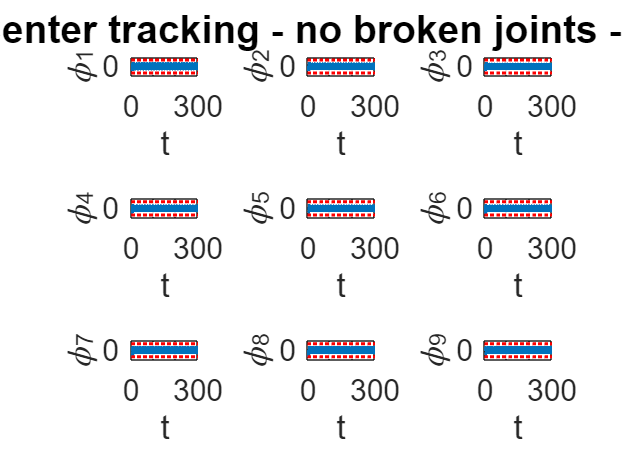

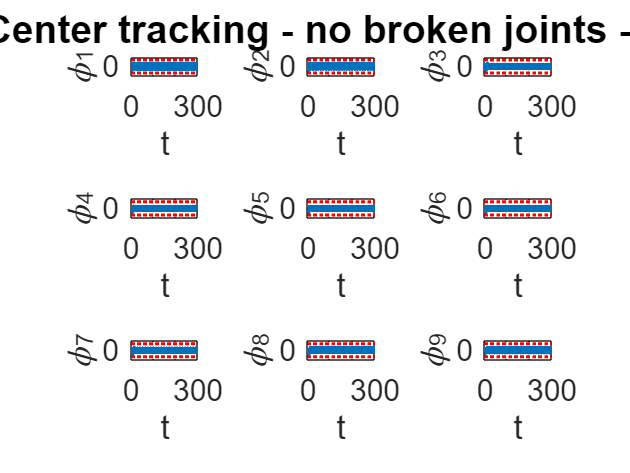

l=cell(param.N-1,1);
for j=1:size(X,2)
    Xa=X{j};
    Ta=T{j};
    figure
    hold on;
    grid on;
    
        
    for i = 1:param.N-1
        subplot(3,3,i)
        plot(Ta,Xa(:,i),'linewidth',3);
        ylabel(strcat('\phi_{', num2str(i), '}'));
        xlabel('t')
        xlim([0, max(Ta)])
        set(gca,'FontSize',20)
        grid on
        hold on
        plot(Ta,ones(size((Ta)))*deg2rad(40),'r:','linewidth',2);
        plot(Ta,ones(size((Ta)))*deg2rad(-40),'r:','linewidth',2);
        hold off
        if i==2
            title(info{j},'FontSize',26)
        end
    end
    
    
end

## Trajectory 

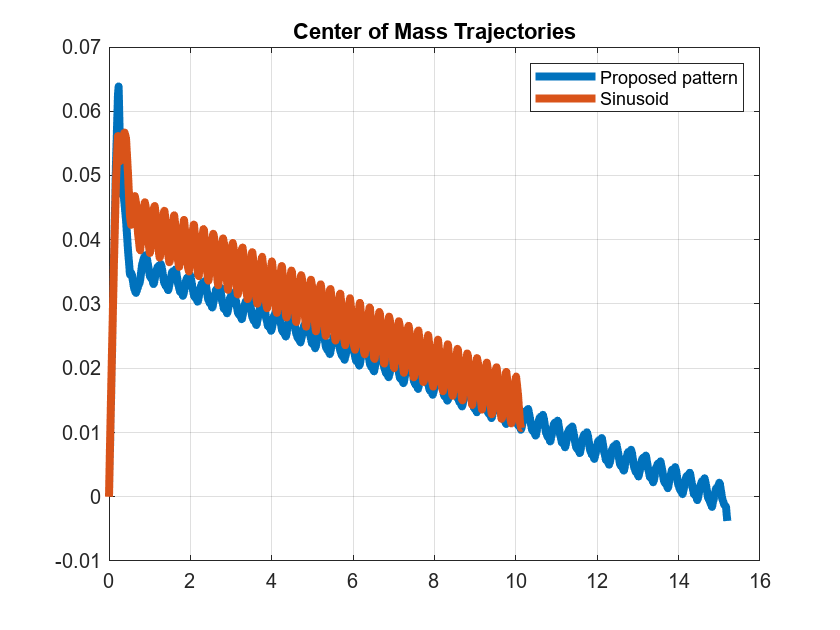

figure
Xa=X{1};
plot(Xa(:,param.N+1),-Xa(:,param.N+2),'linewidth',4);
hold on;
Xa=X{2};
plot(Xa(:,param.N+1),-Xa(:,param.N+2),'linewidth',4);
title("Center of Mass Trajectories")
legend("Proposed pattern", "Sinusoid")
grid on;
hold on;

## Comparison of simulation time: 

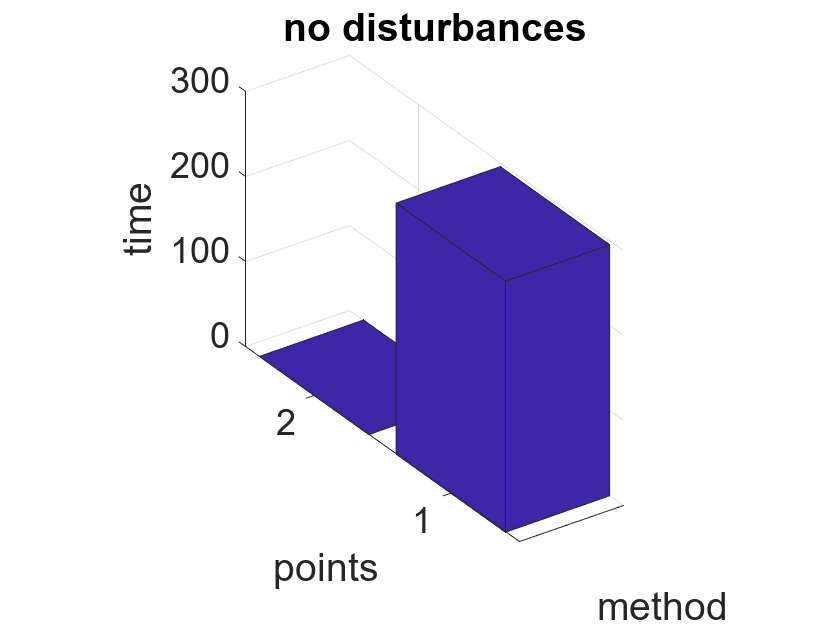

figure
bar3([f1;f2]')
title('no disturbances')
view([145 30])
xlabel('method')
ylabel('points')
zlabel('time')
xticklabels({'center-SJC','center-CC','head-SJC','head-CC'})
set(gca,'FontSize',18)

## Joints position:

Selection of simulation for visualisation:

i=2;
Xa=X{i};
Ta=T{i};
t=Ta';
f=f2;

Calculation of position of each joint x,y:

l=0.2;
D=[diag(ones(param.N-1,1)) zeros(param.N-1,1)]-[zeros(param.N-1,1) diag(ones(param.N-1,1))];
A=[diag(ones(param.N-1,1)) zeros(param.N-1,1)]+[zeros(param.N-1,1) diag(ones(param.N-1,1))];
e=ones(param.N,1);
a=[1; zeros(param.N-1,1)];
if i>=9 % head tracking
    T1=[D; a']; % equation 2.9
else % center tracking
    T1=[D; e'./param.N];
end

Xpa=zeros(size(Xa,1),param.N);  % X coordinate of joints - the centers of undisturbed model
Ypa=zeros(size(Xa,1),param.N);  % Y coordinate of joints - the centers of undisturbed model  
X1a=zeros(size(Xa,1),param.N);  % X coordinate of joints - the beginning of undisturbed model  
Y1a=zeros(size(Xa,1),param.N);  % Y coordinate of joints - the beginning of undisturbed model  
X2a=zeros(size(Xa,1),param.N);  % X coordinate of joints - the end of undisturbed model
Y2a=zeros(size(Xa,1),param.N);  % Y coordinate of joints - the end of undisturbed model

for i=1:size(Xa,1)  % loop for time

    thetaa=zeros(1,param.N);
    thetab=zeros(1,param.N);
    
    for j=param.N:-1:1
        if j==param.N
            thetaa(param.N)=Xa(i,param.N);
            %thetab(param.N)=Xb(i,param.N);
        else
            thetaa(j)=Xa(i,j)+thetaa(j+1);
            %thetab(j)=Xb(i,j)+thetab(j+1);
        end
    end

    Tha(:,i)=(thetaa');
    %Thb(:,i)=thetab';
    
    pXa=Xa(i,param.N+1);
    pYa=Xa(i,param.N+2);
   
    %pXb=Xb(i,param.N+1);
    %pYb=Xb(i,param.N+2);

    Xpa(i,:)=T1^(-1)*[l*A*cos(thetaa)'; pXa];
    Ypa(i,:)=T1^(-1)*[l*A*sin(thetaa)'; pYa];
    X1a(i,:)=Xpa(i,:)+l*cos(thetaa);
    X2a(i,:)=Xpa(i,:)-l*cos(thetaa);
    Y1a(i,:)=Ypa(i,:)+l*sin(thetaa);
    Y2a(i,:)=Ypa(i,:)-l*sin(thetaa);
    
end

## Head & tail trajectory

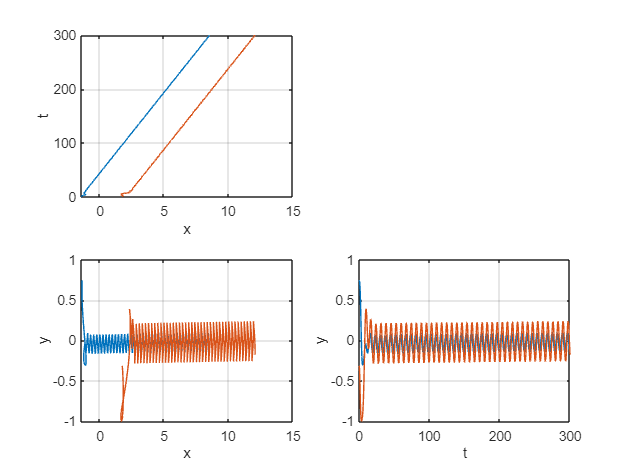

figure
subplot(2,2,3)
plot(X1a(:,param.N),Y1a(:,param.N));
grid on;
hold on;
plot(X1a(:,1),Y1a(:,1));
xlabel('x')
ylabel('y')

subplot(2,2,1)
plot(X1a(:,param.N),Ta);
grid on;
hold on;
plot(X1a(:,1),Ta);
xlabel('x')
ylabel('t')

subplot(2,2,4)
plot(Ta, Y1a(:,param.N));
grid on;
hold on;
plot(Ta, Y1a(:,1));
xlabel('t')
ylabel('y')

## Visualisation data

Calculation of distance between point and snake center:

Th=Tha;
Xp=Xpa;
Yp=Ypa;

Zad_x=t;
Zad_y=t;
f(end)=t(end)+1;
f(f==0)=f(end);
t_s=1;
t0=0;
for i=1:size(f,2)
    t_p=t((t>t0 & t<f(i)));
    t_e=find(t==t_p(end));
    Zad_x(t_s:t_e)=param.Px(i);
    Zad_y(t_s:t_e)=param.Py(i);
    t_s=t_e+1;
    t0=f(i);
    if t_e==size(t,2)
        break
    end
end


Literature

[1] Sibilska-Mroziewicz, A., Mozaryn, J, Hameed A., Fernandez M., Ordys A.: Framework for simulation-based control design evaluation for a snake-robot as an example of multi-body robotic system 

[2] Liljeback, P., Pettersen, K.Y., Stavdahl, Ø., Gravdahl, J.T.: Snake Robots: Modelling, Mechatronics, and Control. Springer London, London (2013) 